close all; 
clear; 
clc;

%planning trajectory
% Tra=csvread('TJlake.csv');
rou=0:0.01:0.5;
%rou=0:0.01:2;
%x=sin(t);cos(t)'];%*
fai=pi/4+rou*0;
Tra=[fai;rou];
%planning trajectory

p=5;            %预测步长
T=0.01;         %采样周期     s
%fossen ship model
u=1.2;v=0;r=0;  %状态变量
taou=0;taor=0;  %输入控制量
err_model=0;

m=23.8000;
Iz=1.7600;
Xdu=-2.0*(1+err_model);
Ydv=-10.0*(1+err_model);
Ndr=-1.0*(1+err_model);
Xu=-0.7225*(1+err_model);
Yv=-0.8612*(1+err_model);
Nr=-1.90*(1+err_model);
Xuu=-1.3274*(1+err_model);
Yvv=-36.2823*(1+err_model);
Nrr=-0.75*(1+err_model);

m11=m-Xdu; 
m22=m-Ydv; 
m33=Iz-Ndr;
d11=-(Xu+Xuu*abs(u)); 
d22=-(Yv+Yvv*abs(v)); 
d33=-(Nr+Nrr*abs(r));

a1=1-d11*T/m11;
a2=2*m22*T/m11*v*r;
%uk=a1*u+a2+T/m11*taou
b1=1-d22*T/ m22;
b2=-2*m11*T/m22*u*r;
%vk=b1*v+b2+T/m22*taov
c1=1-d33*T/m33;
c2=2*(m11-m22)*T/m33*u*v;
%rk=c1*r+c2+T/m33*taor

A=[];B=[];
A2=[];B2=[];
A3=[];B3=[];
for i=1:p
    A=[A;a1^i];
    B=[B;(1-a1^i)/(1-a1)];
    A2=[A2;b1^i];
    B2=[B2;(1-b1^i)/(1-b1)];
    A3=[A3;c1^i];
    B3=[B3;(1-c1^i)/(1-c1)];
end
%up=A*u+B*a2+B*T/m11*taou;
w=u*T;
%wp=A*w+B*T*a2+B*T*T/m11*taou;

%vp=A2*v+B2*b2+B2*T/m22*taov;
w2=v*T;
%wp2=A2*w2+B2*T*b2+B2*T*T/m22*taov;

%rp=A3*r+B3*c2+B3*T/m33*taor;
w3=r*T;
%wp3=A3*w3+B3*T*c2+B3*T*T/m33*taor;

k=0;
wk=w;
wk2=w2;
wrou=sqrt(w*w+w2*w2);
wk3=w3;
% 逐点逐向跟踪目标轨迹
for j=1:length(Tra)-p+1

Tjrou=[];
Tjd=[];
for i1=j:j+p-1
%     Tjrou=[Tjrou;Tra(2,i1)];
    Tjd=[Tjd;Tra(1,i1)];
end

Q=100*eye(size(taou,1)); 
R=100*eye(size(taou,1));   % R=100*eye(size(B,1)); % R=0.5*eye(size(taou,1)); % 优化目标参数，加权矩阵
Q3=100*eye(size(B3,1)); R3=100*eye(size(taor,1));  % 优化目标参数，加权矩阵

k=k+1;
Airou=[];
birou=[];
Aeqrou=[];
beqrou=[];
ubrou=[]; % 控制量U的上、下限
lbrou=[];
nonlcon=[];
options=[];
taou0=1000000*rand(1);
Tr=Tra(2,j);
J=@(taou)((Q*T^8)/m11^4 + (R*T^8)/m11^4)*taou^4 + ((Q*T^6*((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)*4)/m11^3 + (R*T^6*((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)*4)/m11^3)*taou^3 + (Q*((T^4*((w2*((T*d22)/m22 - 1) + (T*m11*w3*u)/m22 + (T*m11*r*w)/m22)^2 + ((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)^2 - Tr^2)*2)/m11^2 + (T^4*((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)^2*4)/m11^2) + (R*T^4*((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)^2*4)/m11^2)*taou^2 + ((Q*T^2*((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)*((w2*((T*d22)/m22 - 1) + (T*m11*w3*u)/m22 + (T*m11*r*w)/m22)^2 + ((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)^2 - Tr^2)*4)/m11)*taou + Q*((w2*((T*d22)/m22 - 1) + (T*m11*w3*u)/m22 + (T*m11*r*w)/m22)^2 + ((T*m22*w3*v)/m11 - w*((T*d11)/m11 - 1) + (T*m22*r*w2)/m11)^2 - Tr^2)^2;
taou1=fmincon(J,taou0,Airou,birou,Aeqrou,beqrou,lbrou,ubrou,nonlcon,options);
% wp=A*w+B*T*a2+B*T*T/m11*taou;
% wp2=A2*w2+B2*T*b2;
% rouproup=wp'*wp+wp2'*wp2;
% rouproup=B'*B*T^4/m11^2*taou^2+((A*w+B*T*a2)'*B+B'*(A*w+B*T*a2))*T^2/m11*taou+(A*w+B*T*a2)'*(A*w+B*T*a2)+(A2*w2+B2*T*b2)'*(A2*w2+B2*T*b2);
% J=rourou-Tjrou'*Tjrou+(B*T*T/m11*taou)'*R*(B*T*T/m11*taou);
% J=(B'*B+B'*R*B)*T^4/m11^2*taou^2+((A*w+B*T*a2)'*B+B'*(A*w+B*T*a2))*T^2/m11*taou+(A*w+B*T*a2)'*(A*w+B*T*a2)+(A2*w2+B2*T*b2)'*(A2*w2+B2*T*b2);
% 优化目标函数min{1/2*x′Hx+f′x+D}
% Hrou=2*(B'*B+B'*R*B)*T^4/m11^2;
% Hrou=2*(B'*B*T^4/m11^2+R);
% frou=((A*w+B*T*a2)'*B+B'*(A*w+B*T*a2))*T^2/m11;
% [tao1,fval,exitflag,output,lambda]=quadprog(Hrou,frou',Airou,birou,[],[],lbrou,ubrou);
% Urou(:,k+1) = 300000 ;%tao1(1);
Urou(:,k+1) = taou1;
wk(:,k+1)=a1*wk(:,k)+a2*T+T*T/m11*Urou(:,k);
w=wk(:,k+1);
wk2(:,k+1)=b1*wk2(:,k)+b2*T;
w2=wk2(:,k+1);
wrou(:,k+1)=sqrt(w*w+w2*w2);

Aid=[];
bid=[];
ubd=[]; % 控制量U的上、下限
lbd=[];
% wp3=A3*w3+B3*T*c2+B3*T*T/m33*taor;
Cd=A3*w3+B3*T*c2;
Hd=2*(B3'*Q3*B3+R3)*(T*T/m33)^2;
fd=((Cd-Tjd)'*Q3*B3+B3'*Q3*(Cd-Tjd))*T*T/m33;% 优化目标函数min{1/2*x′Hx+f′x+D}的矩阵f
[taor1,fvald,exitflagd,outputd,lambdad]=quadprog(Hd,fd',Aid,bid,[],[],lbd,ubd);
Ud(:,k) = taor1(1);
wk3(:,k+1)=c1*wk3(:,k)+c2*T+T*T/m33*Ud(:,k);
w3=wk3(:,k+1);

end


Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Local minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>



Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>


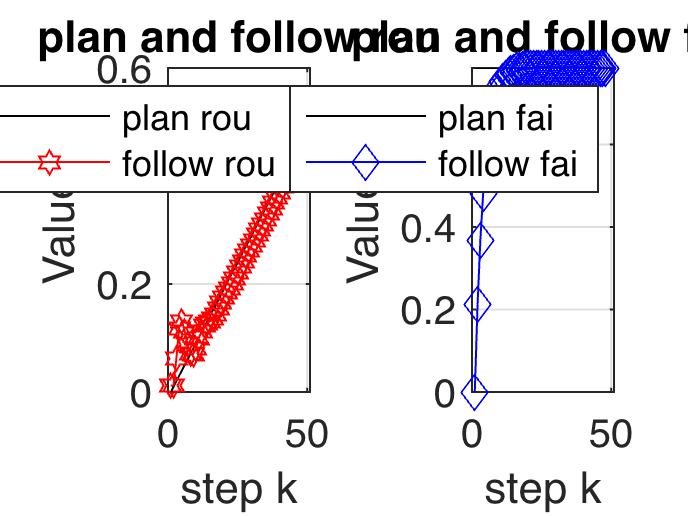


% result show
%绘制双体船位置与姿态,以及规划航线
% TJ=1*Tra;  %轨迹缩放比例为1
figure ()
subplot(121)
K0=1:size(Tra,2);
K1=1:size(wrou,2);
plot(K0,Tra(2,:),'k',K1,wrou(1,:),'r-h');
title('plan and follow rou');xlabel('step k');ylabel('Value');
grid on;legend('plan rou','follow rou');
subplot(122)
K4=1:size(Tra,2);
K5=1:size(wk3,2);
plot(K4,Tra(1,:),'k',K5,wk3(1,:),'b-d');
title('plan and follow fai');xlabel('step k');ylabel('Value');
grid on;legend('plan fai','follow fai');

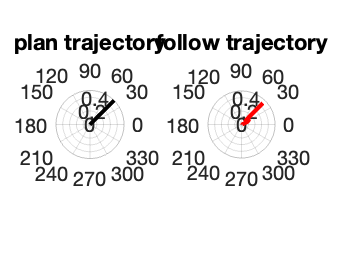


% % result show
%绘制双体船位置与姿态,以及规划航线
figure()
subplot(121)
polarplot(Tra(1,:),Tra(2,:),'k','LineWidth',2);
title('plan trajectory');
subplot(122)
polarplot(wk3(1,:),wrou(1,:),'r','LineWidth',2);
title('follow trajectory');

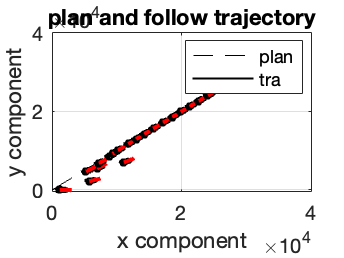


figure()
plot(100000*Tra(2,:).*cos(Tra(1,:)),100000*Tra(2,:).*sin(Tra(1,:)),'--k');
hold on
wr=100000*wrou;
for i2=1:2:size(wr,2)
     catamaran(wr(1,i2),wk3(1,i2))
     %根据位置与艏向绘制双体船平面3DOF图
     hold on
end
title('plan and follow trajectory');xlabel('x component');ylabel('y component');
grid on;legend('plan','tra')

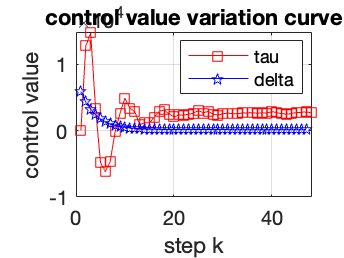


% 绘制每次预测范围控制量的变化
figure ()
K6=1:size(Urou,2);
K8=1:size(Ud,2);
plot(K6,Urou(1,:),'r-s',K8,Ud(1,:),'b-p');
title('control value variation curve');
xlabel('step k');ylabel('control value');
grid on;legend('tau','delta')

% % result show
